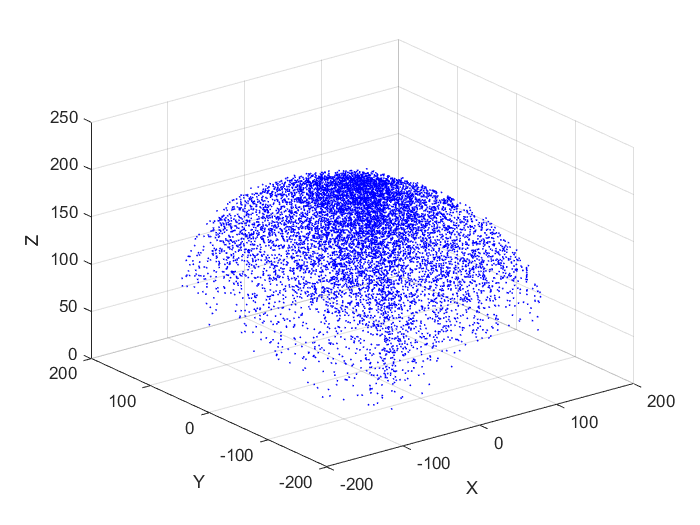

clear;
clc;
%关节限制
theta1_min = 0; %单位 rad
theta1_max = pi/2;
theta2_min = 0;
theta2_max = pi/2;
fai1_min = 0;
fai1_max = 2*pi;
fai2_min = 0;
fai2_max = 2*pi;
s1_min = 0;
s1_max = 100;% 单位mm
s2_min = 0;
s2_max = 100;
N=10000;  %随机次数
theta1 = theta1_min + (theta1_max-theta1_min)*rand(N,1);
theta2 = theta2_min + (theta2_max-theta2_min)*rand(N,1);
fai1 = fai1_min + (fai1_max-fai1_min)*rand(N,1);
fai2 = fai2_min + (fai2_max-fai2_min)*rand(N,1);
%s1 = s1_min + (s1_max - s1_min)*rand(N,1);
%s2 = s2_min + (s2_max - s2_min)*rand(N,1);
modX=zeros(N,1);
modY=zeros(N,1);
modZ=zeros(N,1);
for n=1:1:N
    TEMP0 = PositionEnd(theta1(n),theta2(n),fai1(n),fai2(n));
    modX(n)=TEMP0(1);
    modY(n)=TEMP0(2);
    modZ(n)=TEMP0(3);
end
%plot3(modX,modY,modZ,'-o','Color','b','MarkerSize',0.5);
scatter3(modX,modY,modZ,0.5,'blue')
xlabel('X');
ylabel('Y');
zlabel('Z');